              FIND THE ARC LENGTH AND PERIMETER 

Example-17. A manufacturer of corrugated metal roofing wants to produce

panels that are 28 in. wide and 2 in. thick by processing flat sheets of metal

as shown in the figure. Find the width w of a flat metal sheet that is needed

to make a 28-inch panel

SOLUTION:

The profile of the roofing takes the shape of a sine wave

The sine wave has amplitude  1 and period 14 

Since it goes through two periods ina distance of 28, so the eequation y=1sin($\frac{2\pi }{14}$x) . The width w of the flat metal sheet needed to make the panel is the arc length of the sine curve from x=0 tox=28 . We set up the integral to L=$\int_0^{28} \sqrt{{\int_0^{28} \sqrt{1+\left\lbrack \frac{\pi }{7}\cos \left(\frac{\pi }{7}x\right)\right\rbrack }}^2 }$dx

syms x
y=sin(pi*x/7)

$$y = \sin\left(\frac{\pi \,x}{7}\right)$$

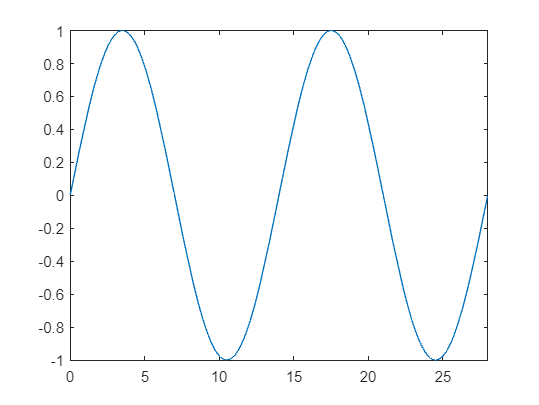




fplot(y,[0,28])% plot to see the sine curve between x=0 to x=28

Formuls for the length is L=$\sqrt{1+\left({\frac{\textrm{dy}}{\textrm{dx}}}^2 \right)}$dx , first we find dy/dx , then the intesrted 

df=diff(y)

$$df = \frac{\pi \,\cos\left(\frac{\pi \,x}{7}\right)}{7}$$

integrand=sqrt(1+df^2)

$$integrand = \sqrt{\frac{\pi^{2}\,{\cos\left(\frac{\pi \,x}{7}\right)}^{2}}{49}+1}$$





L = int(integrand,x, 0,28)

$$L = \int_{0}^{28}\sqrt{\frac{\pi^{2}\,{\cos\left(\frac{\pi \,x}{7}\right)}^{2}}{49}+1}\mathrm{d}x$$

double(L)

ans = 29.3607

EXAMPLE 18 

Example-18. A steady wind blows a kité due west.

The kite's height above ground from horizontal

position x=0 to x-80 ft is given by

y = 150-— (x-50) Find the distance

40

traveled by the kite.

syms x 
y=150-(1/40)*(x-50)^2

$$y = 150-\frac{{\left(x-50\right)}^{2}}{40}$$

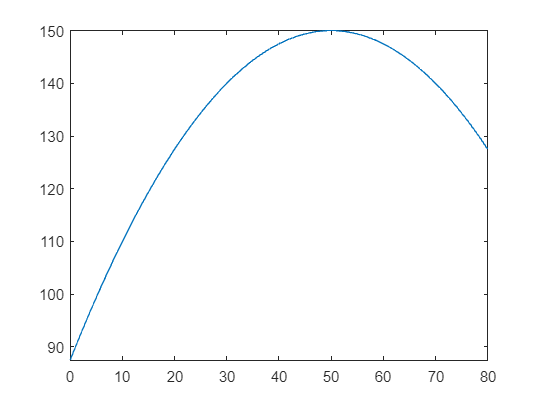




fplot(y,[0 80])

df=diff(y)

$$df = \frac{5}{2}-\frac{x}{20}$$



integrand=sqrt(1+(df)^2)

$$integrand = \sqrt{{\left(\frac{x}{20}-\frac{5}{2}\right)}^{2}+1}$$

L=double(int(integrand,0,80))

L = 122.7761

EXAMPLE 19)

A hawk flying at at an altitude of 180 m accidentally

prey. The parabolic trajectory of the falling prey is described

until it hits the ground, where y is its heigt

equation y = 180-$\frac{x^2 }{45}$

the ground and x is the horizontal distance traveled in meters,

the distance traveled by the prey from the time it is dropped until

it hits the ground. Express your answer correct to the nearest to

meter.

syms x
y=180-(x^2/45) 

$$y = 180-\frac{x^{2}}{45}$$




% The prey hits the ground when y=0
hits_the_ground=solve(y==0,x>=0)

$$hits\_the\_ground = 90$$

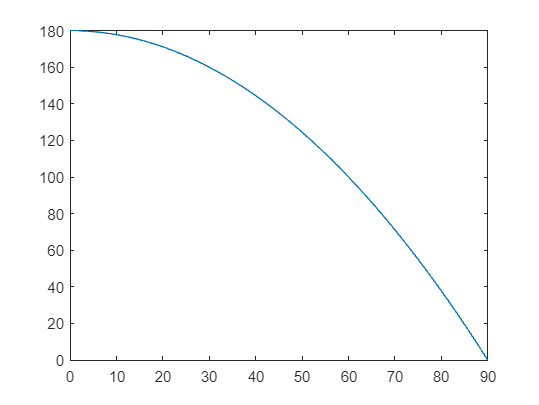




fplot(y,[0 90])

df=diff(y)

$$df = -\frac{2\,x}{45}$$



integrand=sqrt(1+(df)^2)

$$integrand = \sqrt{\frac{4\,x^{2}}{2025}+1}$$

distance=double(int(integrand,0,90))

distance = 209.1053

EXAMPLE 20)

Find the area common to the circles r=a sqrt:

r-2*a*cos (theta)

we are using polar form

syms theta a
r1(theta)=sqrt(2)*a

$$r1(theta) = \sqrt{2}\,a$$


r2(theta)=2*a*cos(theta)

$$r2(theta) = 2\,a\,\cos\left(\theta \right)$$



area1=(1/2)*int((r1(theta))^2,theta,0,pi/4)

$$area1 = \frac{\pi \,a^{2}}{4}$$



area2=(1/2)*int((r2(theta))^2,theta,0,pi/4)

$$area2 = \frac{a^{2}\,\left(\pi +2\right)}{4}$$


 
area=2*(area1 + area2)

$$area = \frac{\pi \,a^{2}}{2}+\frac{a^{2}\,\left(\pi +2\right)}{2}$$

Perimeter

dr1(theta)=diff(r1(theta))

$$dr1(theta) = \sqrt{2}$$



dr2(theta)=diff(r2(theta))

$$dr2(theta) = -2\,a\,\sin\left(\theta \right)$$



integrand1=sqrt((r1(theta))^2+(dr1(theta))^2)

$$integrand1 = \sqrt{2}\,\sqrt{a^{2}+1}$$



perimeter1=int(integrand1,theta,0,pi/4)

$$perimeter1 = \frac{\pi \,\sqrt{2}\,\sqrt{a^{2}+1}}{4}$$



integrand2=sqrt((r2(theta))^2+(dr2(theta))^2)

$$integrand2 = 2\,\sqrt{a^{2}\,{\cos\left(\theta \right)}^{2}+a^{2}\,{\sin\left(\theta \right)}^{2}}$$




perimeter2=int(integrand2,theta,0,pi/4)

$$perimeter2 = \frac{\pi \,\sqrt{a^{2}}}{2}$$




perimeter=2*(perimeter1+perimeter2)

$$perimeter = \pi \,\sqrt{a^{2}}+\frac{\pi \,\sqrt{2}\,\sqrt{a^{2}+1}}{2}$$